# Beam Bending

**Learning Goals**

- Solve for beam support reactions symbolically.

- Solve for the moment function of a loaded beam.

- Plot shear and moment diagrams.

- Compute the bending stress in a loaded beam.

## Support Reactions

When a beam is loaded, its supports provide reaction forces that balance the load. 

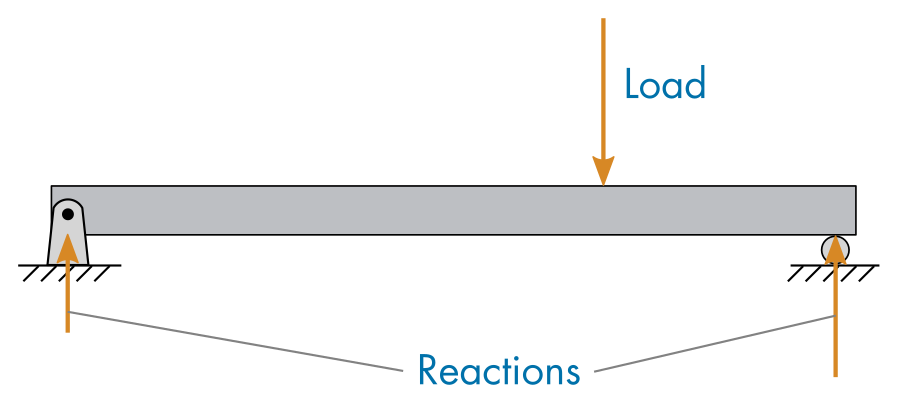

*A beam experiencing a load. The reaction forces balance the force and moment caused by the load, maintaining the static equilibrium. *

The beam is assumed to be in static equilibrium. This implies that the sums of forces and moments must be zero:

$\sum F_i = 0$    and     $\sum M_i = 0$

In a complex geometry, there might be forces in multiple directions and moments about more than one axis. Each direction and axis of rotation would have its own equilibrium equation. In some cases, there could be more unknown forces than equilibrium equations, resulting in a statically indeterminate system. For the purposes of this script, only vertical forces and moments about a single axis of statically determinate systems will be analyzed.

In this section, you will learn to use the Symbolic Math Toolbox to solve for beam support reactions. Before applying the Symbolic Math Toolbox to the mechanical system, there is a brief activity where you can learn the basics of working with the Symbolic Math Toolbox.

### Symbolic Math Toolbox Basics

  **Activity 1. **In this activity, you will solve the system of equations


$$\begin{array}{rl} x + 4y &= 3  \\ 3x - 2y &= 6 \end{array}$$


using the Symbolic Math Toolbox. For a more complete introduction to the Symbolic Math Toolbox, take the [Introduction to Symbolic Math with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic) self-paced online training course.

**Task 1. **Define symbolic variables `x` and `y` using the [`syms`](https://www.mathworks.com/help/symbolic/syms.html) command. For example, to define variables `w` and `z`, you would use

% Write your code here
syms x y

**Task 2. **Define the first equation using the symbolic variables and assign the result to `eq1`. Use `==` for the equals sign in the equation. For example, to define the equation $3w + z = 2$ and assign it to a variable named `eq`, you could use

eq1 = x + 4*y == 3

**Task 3. **Define the second equation and store it in `eq2`.

eq2 = 3*x - 2*y == 6

**Task 4. **Solve the equations created in **Tasks 3 **and** 4 **using [`solve`](https://www.mathworks.com/help/symbolic/sym.solve.html). For example, to solve two equations stored in `eqA` and `eqB`, you could use

solve(eq1,eq2)

If correct, you should find the solution $(15/7, 3/14)$.

### Solve for Support Reactions

There are two main steps required to solve for the support reactions of a loaded beam using the Symbolic Math Toolbox.

- Draw the free-body diagram and set up the equilibrium equations.

- Define and solve the symbolic equations in MATLAB.

**Example 1. **Solve for the support reactions of the beam illustrated below.

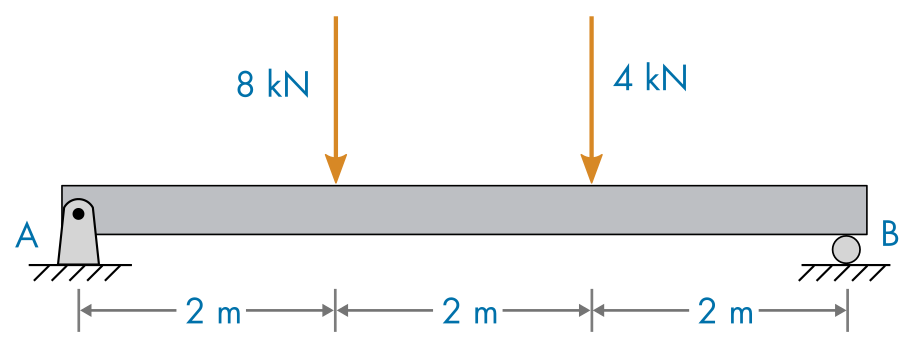

The supports at points A and B generate reaction forces $F_A$ and $F_B$. These act to balance the forces in the vertical direction as well as the moments. The moments are computed about the pin at point A.

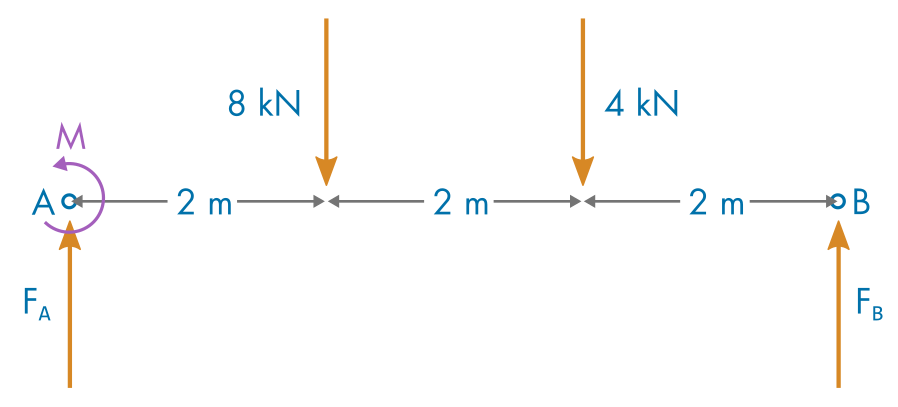

This implies that the sum of the forces in the vertical direction is


$$F_A + F_B - 8 - 4 = 0$$


Summing the moments about A yields


$$2(-8) + 4(-4) + 6F_B = 0$$


To solve these equations in MATLAB, define symbolic variables for $F_A$ and $F_B$, then solve.

syms F_A F_B
feq = F_A + F_B - 8 - 4 == 0;
meq = 16 + 16 - 6*F_B == 0;
sol = solve(feq,meq)

To view the solutions as decimal approximations, you can convert them to doubles using the [`double`](https://www.mathworks.com/help/matlab/ref/double.html) function. Note that to extract the values from the solution object `sol`, you can use the dot notation: 

double(sol.F_A)
double(sol.F_B)

 **Exercise 1.** Solve for the support reactions $F_A$ and $F_B$ for the loaded beam illustrated below. Store your results as doubles in variables `FA` and `FB`.

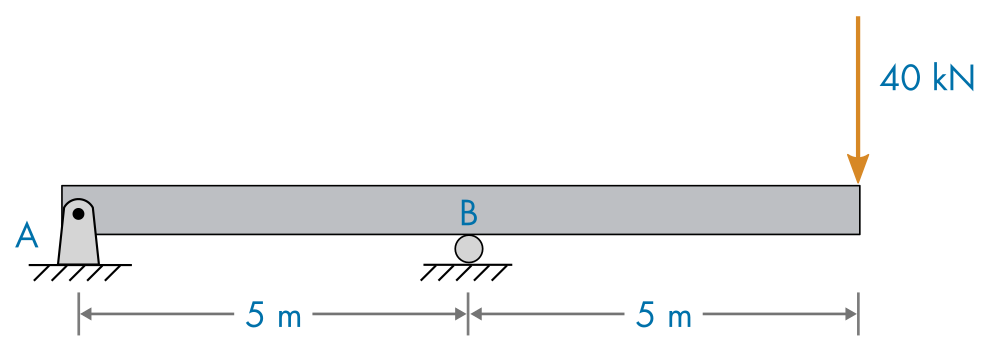

% Write your code here
syms F_A F_B
eqF = F_A + F_B - 40 == 0;
eqM = F_B*5 - 40*10 == 0;
sol = solve(eqF,eqM);
FA = double(sol.F_A)
FB = double(sol.F_B)

## Shear and Moment Diagrams

Shear and moment diagrams offer insight into the loading pattern experienced by a beam. The shear diagram illustrates how much shear force is experienced by each beam region, while the moment diagram plots the moments along the beam. By examining the moment diagram, you can identify regions of high bending stress.

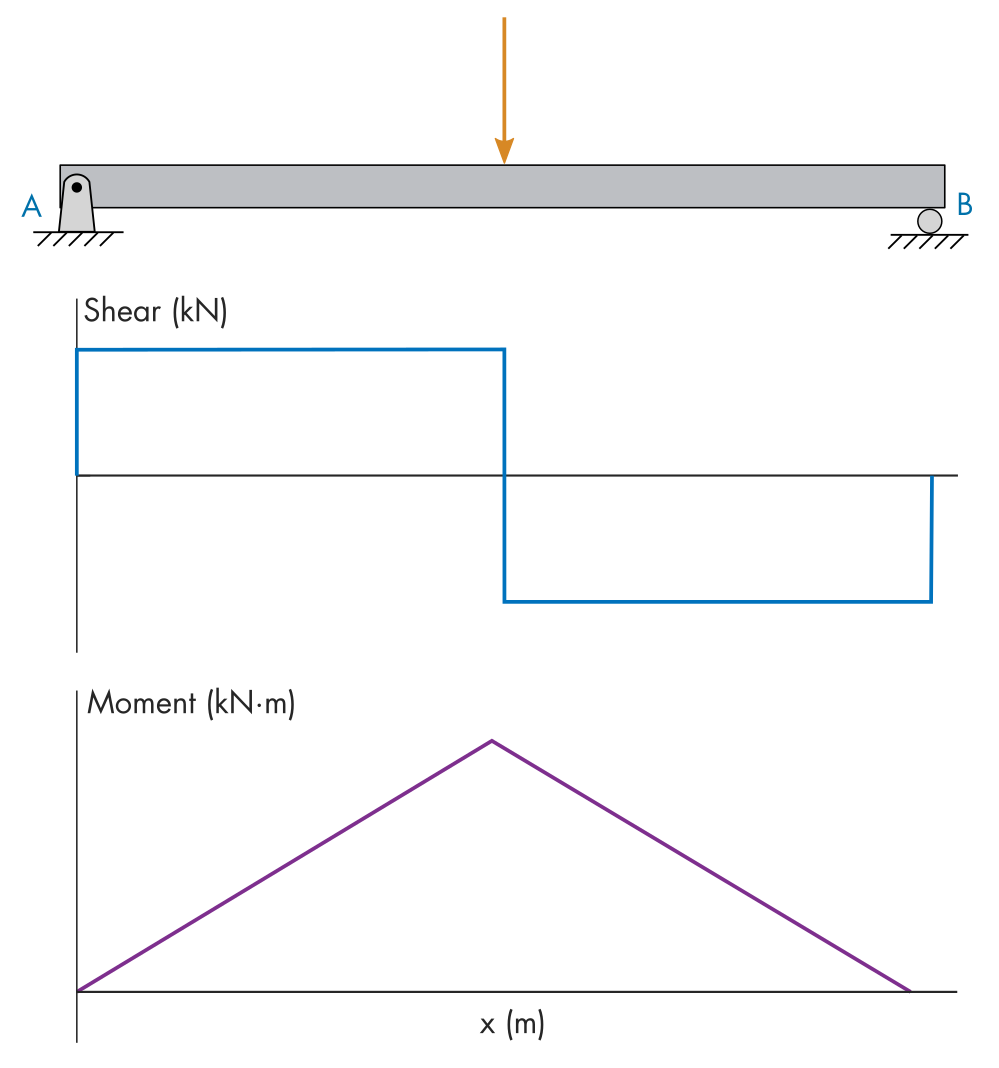

*Shear and moment diagrams for a beam loaded by a point force at its center. The greatest moment is observed at the loading point.*

Shear and moment diagrams can be qualitatively constructed by hand. However, to quantitatively analyze the bending stress, it is necessary to compute a function for the moment explicitly. The moment function can be computed analytically from the loading conditions using the mathematical relationships between the load, shear, and moment. Let the load distribution be $f(x)$, the shear $S(x)$, and the moment $M(x)$. Then the relationships are


$$\frac{dS}{dx} = -f(x)$$



$$\frac{dM}{dx} = S(x)$$


These relationships imply that you can calculate the moment function by computing two integrals:


$$S(x) = -\int f(x) \ dx$$
  


$$M(x) = \int S(x) \ dx$$


To accelerate this process, you can use the Symbolic Math Toolbox to do the math for you. In this section, you will learn to use the Symbolic Math Toolbox to compute the moment and create shear and moment diagrams. Before applying the Symbolic Math Toolbox to computing the moment, a brief activity will show you how to define and integrate symbolic functions.

### Integrating Functions with the Symbolic Math Toolbox

  **Activity 2. **In this activity, you will define, integrate, and plot symbolic functions. 

**Task 1. **Define a symbolic variable for the independent variable $x$ and a function $f(x)$. For example, to define a symbolic variable for a function $g(z)$, you could use

% Write your code here
syms f(x)

**Task 2. **Define $f(x)$ to be the quadratic function:


$$f(x) = x^2 - 1$$


To define the function itself (rather than the variable in which it will be stored), you can use standard mathematical notation. For example, to define the function 


$$g(z) = \sin(z^2)$$


you could use

f(x) = x^2 - 1

**Task 3. **Plot the function $f(x)$ for $x$ in $[-2,2]$. You can plot a symbolic function `g(x)` using [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html) with the syntax

where `g(x)` is the symbolic function to be plotted and `xinterval` is the interval over which the plot will be created (e.g., `[-3,3]`).

fplot(f(x),[-2,2])

**Task 4**. Integrate the function $f(x)$ over the interval $[-3,3]$ and store the result in `intVal`. You can integrate a function $g(x)$ over an interval $[a,b]$ using the [`int`](https://www.mathworks.com/help/symbolic/sym.int.html) function with the syntax:

intVal = int(f(x),-3,3)

**Task 5. **To create the moment diagrams, you'll want to compute the indefinite integral function, rather than a definite integral. Compute the indefinite integral of $f(x)$ and store the result in `F(x)`. For example, to compute the indefinite integral of a function $g(x)$, you could use

The constant of integration is assumed to be zero. In cases where a different constant of integration is required, you can add it to the result.

F(x) = int(f(x))

**Task 6. **Plot the function $F(x)$ on $[-3,3]$ using `fplot`.

fplot(F(x),[-3,3])

If correct, your plot should appear as:

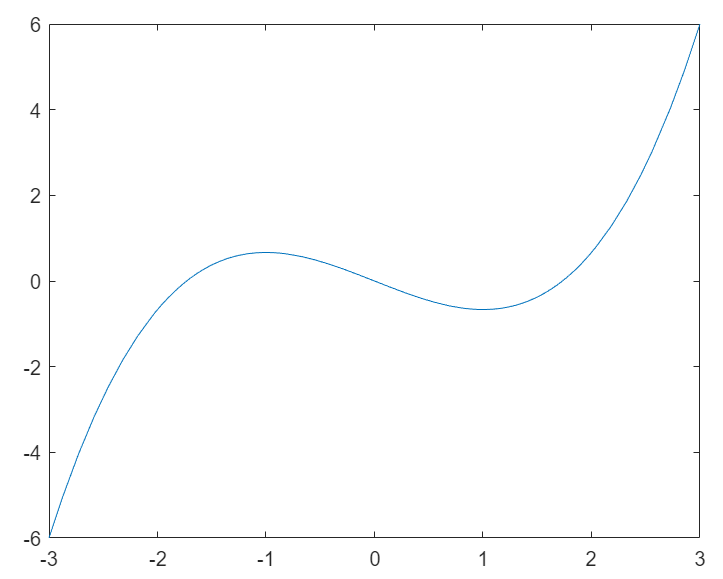

### Create Shear and Moment Diagrams

To create shear and moment diagrams in MATLAB, there are four main steps:

- Solve for the support reactions.

- Define the shear force function.

- Compute the moment function as the integral of the shear function.

- Plot the shear and moment functions.

**Example 2**. Create a plot of the shear and moment diagrams for the beam illustrated below using the Symbolic Math Toolbox.

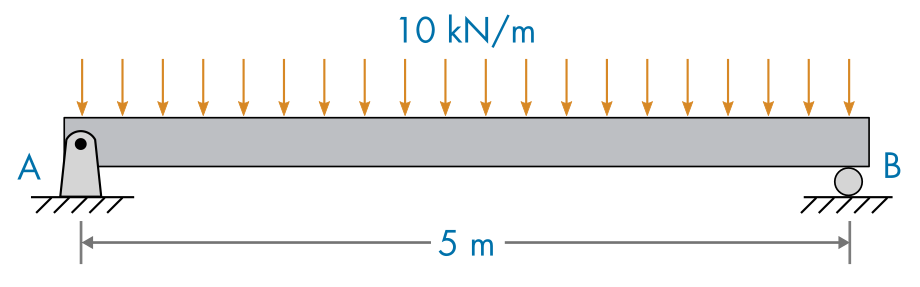

**Step 1. Solve for the support reactions. **

First, define an equation for the vertical force conservation. You can integrate the distributed load density to compute the force that it contributes.

syms F_A F_B
eqF = F_A + F_B - int(sym(10),0,5) == 0

Now, define an equation for the moment about point A. To solve for the moments created by the distributed load, you can integrate the incremental moments over the beam. So the overall momentum equation is 


$$5 F_B - \int_0^5 10x \ dx = 0$$


 Note that the moments in the counterclockwise direction are considered to be positive. 

eqM = 5*F_B - int(10*x,0,5) == 0

Now solve for the support reactions and store them in new variables.

sol = solve(eqF,eqM);
FA = double(sol.F_A)
FB = double(sol.F_B)

**Step 2. Define the shear function.**

The support reaction at point $A$ acts as the initial value for the shear force. Then, the distributed load continuously contributes a force equal to the integral of the force density. Note that this is an indefinite integral as the shear force from the distributed load acts over the full length of the beam. The final value of the shear force returns to zero based on the reaction $F_B$, but it is not necessary to include this in the diagram, since it is at the boundary. The symbolic function is defined below as $S(x)$.

% Compute the shear along x
S(x) = FA - int(sym(10))

**Step 3. Compute the moment function.**

The moment function is the integral of the shear function. Therefore, you only need to integrate to obtain it.

% Compute the moment along x
M(x) = int(S(x))

**Step 4. Plot the shear and moment functions.**

To plot the shear and moment functions use [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html). Don't forget to label the axes using [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html) and [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html). To make the graph easier to line up, you can use [`subplots`](https://www.mathworks.com/help/matlab/ref/subplot.html).

% Shear diagram
subplot(2,1,1)
fplot(S(x),[0,5])
ylabel("Shear (kN)")
% Moment diagram
subplot(2,1,2)
fplot(M(x),[0,5])
ylabel("Moment (kN·m)")
xlabel("x (m)")

Notice that the greatest moment is observed at the center of the beam.

 **Exercise 2.** Create the shear and moment diagrams for the loaded beam illustrated below. The force density of the distributed load is $3 x$ (kN/m). Use the previous example as a guide to complete the exercise.

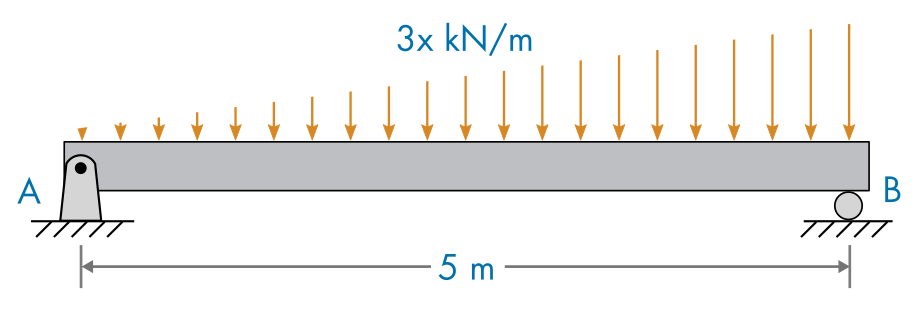

% Write your code here

% Reactions
syms F_A F_B x
eqF = F_A + F_B - int(3*x,0,5) == 0;
eqM = 5*F_B - int(3*x*x,0,5) == 0;
sol = solve(eqF,eqM);
FA = double(sol.F_A)
FB = double(sol.F_B)
% Shear and moment
S(x) = FA - int(3*x)
M(x) = int(S(x))
% Diagram
subplot(2,1,1)
fplot(S(x),[0,5])
ylabel("Shear (kN)")
subplot(2,1,2)
fplot(M(x),[0,5])
ylabel("Moment (kN·m)")
xlabel("x (m)")

Symbolic computations are powerful because they can be reused to compute solutions under a variety of conditions. The following activity allows you to reuse code similar to the one you wrote in the previous exercise to compute beam loadings under various conditions. However, instead of defining the shear force function as in the previous example, you define the loading density function in kN/m.

  **Activity 3. **The code below plots a diagram along with the shear and moment diagram given the specified loading density function. 

syms x
length = 5; % Length of the beam (m)
rollerPos = 5; % Roller support position (m) (must be <= length)
pinPos = 0; % Pin support position (m) (cannot equal the roller position)
Fapplied = -10; % Applied force density (kN/m) as a function of x 
shearMomentDiagram(length,Fapplied,rollerPos,pinPos); 

**Task 1. **Run the section to show the default diagram. Ensure that the parameters are set to the defaults:

- `length = 5`

- `rollerPos = 5`

- `pinPos = 0`

- `Fapplied = -10`

Note that this shows the same loading conditions as **Example 2** above.

**Task 2. **Check your solution from the previous exercise by setting the beam to have the same characteristics as in** Exercise 2**. Set the parameters to: 

- `length = 5`

- `rollerPos = 5`

- `pinPos = 0`

- `Fapplied = -3x`

**Task 3. **You can create a load on only a section of the beam using the [`heaviside`](https://www.mathworks.com/help/symbolic/heaviside.html) function. The Heaviside step function is defined as


$$H(x) = \left\{ \begin{array}{rl} 1, & x > 0 \\ 0, & x \leq 0 \end{array}\right.$$


Set the applied force density function (`Fapplied`) to 

to create a loading only on the right side of the beam. Set the other parameters to 

- `length = 10`

- `rollerPos = 5`

- `pinPos = 0`

**Task 4. **To create a more localized load, you can use a product of two Heaviside functions. Set the applied force density function (`Fapplied`) to 

Set the other parameters to the values used in **Task 3**.

**Task 5. **There is no obvious way to add a point load to the force density, but it is possible. To do so, you can use a Dirac delta function, $\delta(x)$. In the Symbolic Math Toolbox, you can create a Dirac delta using [`dirac`](https://www.mathworks.com/help/symbolic/sym.dirac.html). The Dirac delta function has the property that it is zero almost everywhere, but integrating it through $x=0$ will produce a value of one. Set the force density function to 

to create a 50 kN load at $x = 5$. Note that the load will not appear in the diagram as an arrow but will be reflected in the shear and moment diagrams. Set the other parameters to the values used in **Task 3**.

**Task 6. **Try adjusting the pin and roller positions. How do the moments change if both supports are close to one end of the beam?

## Bending Stress

The bending stress in a beam can be computed from the geometry and loading conditions of the beam. In this section, you will compute the bending stress in a simple rectangular beam. The bending stress in a beam can be computed as


$$\sigma_b = -\frac{My}{I}$$


where $M$ is the moment, $y$ is the distance from the neutral axis in the vertical direction, and $I$ is the area moment of inertia about the neutral axis. For a rectangular beam, the neutral axis passes through the centroid of the beam's cross-section.

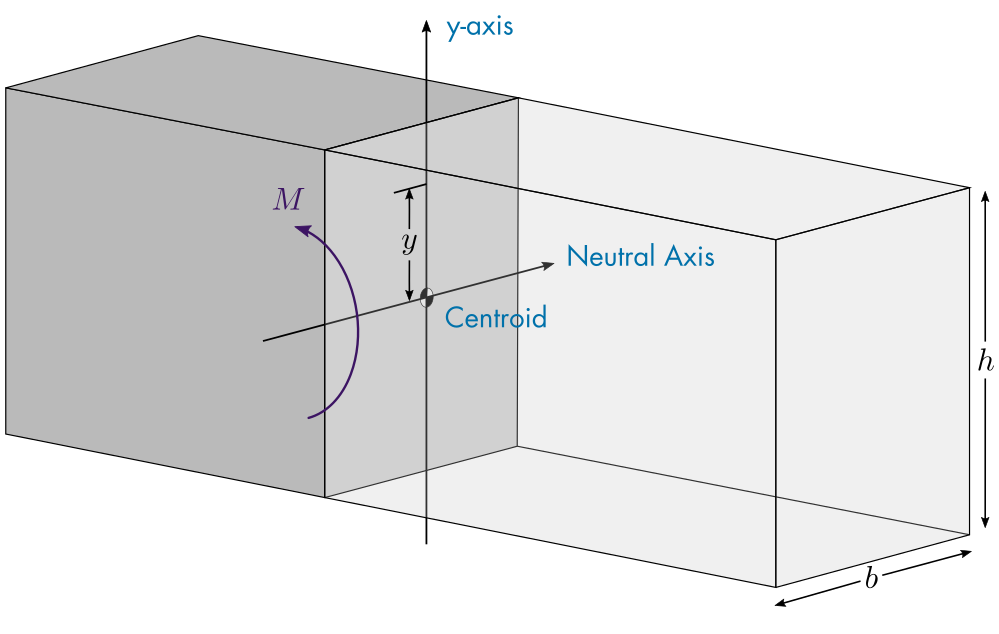

*Cross-section of a rectangular beam with labels relevant to the bending stress.*

For a rectangular beam, the area moment of inertia about the neutral axis is 


$$I = \frac{b h^3}{12}$$


A different formula exists for other geometries, like a cylindrical beam with a circular cross-section. The bending stress increases in magnitude as you move along the y-axis away from the centroid. The equation for bending stress implies that the magnitude will be greatest at $y = \pm \frac{h}{2}$. There are three major steps to computing the maximum bending stress in a loaded beam:

- Compute the moment function and identify its maximum value.

- Compute the area moment of inertia about the neutral axis.

- Evaluate the bending stress using the formula.

**Example 4** illustrates this process.

### Using Units with the Symbolic Math Toolbox

You can use units from the Symbolic Math Toolbox in your computations. These allow you to easily compute solutions in different units and verify that the units of your answer match the expected units. The short example below demonstrates how to use units in your computations.

**Example 3.** Consider a distributed load of 15 kN/m across a 11 m beam. What is the resultant point load on the beam in lbf?

First, create the unit object using [`symunit`](https://www.mathworks.com/help/symbolic/symunit.html). The resulting object u contains a wide variety of units.

u = symunit;

You can now define your values by multiplying them by the correct unit. To specify a unit, use `u.``unit`.

f = 15*u.kN/u.m
L = 11*u.m

Calculating the point force yields

pF = f*L

To convert the units to lbf, use the [`unitConvert`](https://www.mathworks.com/help/symbolic/unitconvert.html) function on pF.

pF = unitConvert(pF,u.lbf)

The symbolic form is a little messy. You can convert it to a simpler notation by using the [`vpa`](https://www.mathworks.com/help/symbolic/vpa.html) function. The second entry to `vpa` indicates how many significant digits should be used.

vpa(pF,5)

To learn more about using units, have a look at the [Units of Measurement Tutorial](https://www.mathworks.com/help/symbolic/units-of-measurement-tutorial.html). 

**Example 4**. Compute the greatest bending stress value (in MPa) in the beam illustrated below.

Assume that the beam is rectangular with a cross-sectional height of 20 cm and a width of 30 cm.

**Step 1. Compute the moment function and identify its maximum value.**

In **example 2**, the moment along the beam was computed to be 

syms x
M(x) = -5*x^2 + 25*x

The maximum value occurs when the derivative of the parabola is zero. The derivative of the function is computed using [`diff`](https://www.mathworks.com/help/symbolic/diff.html).

xcrit = solve(diff(M(x)) == 0)

This implies the maximum value of the moment (in kN$\cdot$m) is

u = symunit;
Mmax = M(xcrit)*u.kN*u.m

**Step 2. Compute the area moment of inertia about the neutral axis.**

The area moment of inertia for the rectangular beam is computed using the formula. Don't forget to convert the units – or use the Symbolic Math Toolbox to keep track of the units.

b = 30*u.cm;
h = 20*u.cm;
I = b*h^3/12

**Step 3. Evaluate the bending stress using the formula.**

The bending stress is maximum at the extremities of the cross-section, where $y$ is greatest in magnitude. This occurs at $y = -0.1$ m, as the beam has a height of 0.2 m. Therefore, the bending stress is

y = -0.1 * u.m
sigma = -Mmax*y/I % kPa

Converting this to MPa gives

sigma = unitConvert(sigma,u.MPa)

Or, in decimal form:

vpa(sigma,10)

**Exercise 3**. Compute the greatest value of the bending stress (in MPa) in the beam illustrated below.

Assume that the beam is rectangular with a cross-sectional height of 10 cm and a width of 50 cm.

% Write your code here
syms x
M(x) = -x^3/2 + 25/2*x;
xcrit = solve(diff(M(x)) == 0);
u = symunit;
Mmax = double(M(xcrit(2)))*u.kN*u.m;
b = 50*u.cm;
h = 10*u.cm;
I = b*h^3/12;
y = -5*u.cm;
sigma = -Mmax*y/I;
sigma = vpa(unitConvert(sigma,u.MPa),5)

**Helper Functions**

function shearMomentDiagram(length,Fapplied,rollerPos,pinPos)
    % Creates a shear/moment diagram 
    clf

    if(rollerPos > length)
        rollerPos = length;
        disp("The roller position must be less than the length." + ...
            newline + "It has been automatically set to the length.")
    end
    if(pinPos == rollerPos)
        error("Pin position cannot equal the roller position. Please adjust the positions.")
    end
    
    % Symbolic calculations
    syms x F_A F_B
    Feq = int(sym(Fapplied),0,length) + F_A + F_B == 0;
    Meq = F_B*(rollerPos-pinPos) + int(Fapplied*(x-pinPos),0,length) == 0;
    sol = solve([Feq,Meq],[F_A,F_B]);
    FA = double(sol.F_A);
    FB = double(sol.F_B);
    % Symbolic shear and moment 
    syms x1 x2
    shearForce = FA*heaviside(x1-pinPos) + FB*heaviside(x1-rollerPos) + int(Fapplied,0,x1);
    moment = int(shearForce,0,x2);

    % Build the figure
    figure("Position",[0 0 600 600])

    % Bar diagram
    subplot("Position",[0.05,0.7,0.9,0.25])
    xLims = barDiagram(length,FA,FB,Fapplied,rollerPos,pinPos);

    % Shear diagram
    subplot("Position",[0.05,0.4,0.9,0.25])
    shearDiagram(length,xLims,shearForce)

    % Moment diagram
    subplot("Position",[0.05,0.05,0.9,0.25])
    momentDiagram(length,xLims,moment)

end

function xLims = barDiagram(length,FA,FB,FappliedSym,rollerPos,pinPos)
    
    % Force arrow calculations
    maxLength = 10;
    xApplied = linspace(0,maxLength,40);
    Fapplied = double(subs(FappliedSym,xApplied));

    % Settings
    barColor = [0.7 0.7 0.7];
    supportColor = [0.8 0.8 0.8];
    barHeight = 0.35;
    offsetx = 0.0;
    rCirc = 0.1;
    pinHeight = 0.1;
    quiverLW = 1;
    
    circCenter = [rollerPos,-rCirc]; % (xc,yc)
    pinCenter = [pinPos,pinHeight];
    diagramAxisLims = [-rCirc*3,maxLength+rCirc*3,-barHeight,barHeight*2];
    xLims = diagramAxisLims(1:2);
    
    % Bar
    barx = [-offsetx, length+offsetx, length+offsetx, -offsetx];
    bary = [0 0 barHeight barHeight];
    patch(barx,bary,barColor)
    hold on

    % Pin support
    theta = linspace(pi-0.5,0+0.5,50);
    xSupport = rCirc*cos(theta) + pinCenter(1);
    ySupport = rCirc*sin(theta) + pinCenter(2);
    xSupport = [pinPos-0.125, xSupport,pinPos+rCirc*2-0.075];
    ySupport = [-2*rCirc, ySupport, -2*rCirc];
    patch(xSupport,ySupport,supportColor)
    plot(pinCenter(1),pinCenter(2),".",SeriesIndex = "none",MarkerSize = 10)

    % Circle (roller support)
    theta = linspace(0,2*pi,50);
    xcirc = rCirc*cos(theta) + circCenter(1);
    ycirc = rCirc*sin(theta) + circCenter(2);
    patch(xcirc,ycirc,supportColor);    

    % Force scaling
    Fscale = 3*barHeight/max(abs([FA,FB,Fapplied]));

    % Applied force arrow(s)
    vApplied = Fapplied*Fscale;
    yApplied = xApplied*0+barHeight-(vApplied<0).*vApplied;
    idx = xApplied <= length;
    xApplied = xApplied(idx);
    vApplied = vApplied(idx);
    yApplied = yApplied(idx);
    xText = mean(xApplied.*abs(vApplied))./mean(abs(vApplied));
    quiver(xApplied,yApplied,xApplied*0,vApplied,"Autoscale","off",SeriesIndex = 2)

    % Reaction force arrows
    xr = [pinPos, rollerPos];
    vr = [FA*Fscale, FB*Fscale];
    yr = -vr + vr.*(vr < 0);
    quiver(xr,yr,xr*0,vr,"AutoScale","off","LineWidth",quiverLW,SeriesIndex = 2)
    yrText = -abs(vr);
    text(xr,yrText,["F_A = " + num2str(FA,3) + " kN","F_B = " + num2str(FB,3) + " kN"],...
        "HorizontalAlignment","center","VerticalAlignment","top")

    axis(diagramAxisLims)
    axis equal
    axis off

    ax = gca;
    ax.Clipping = "off";

    yAxLims = get(gca,"ylim");
    labelPosY = yAxLims(1) - rCirc;
    % Length label
    xs = sort([0 pinPos rollerPos length]);
    plot(xs,ones(1,4)*labelPosY,"|",SeriesIndex = "none",LineWidth = 1)
    for k = 1:(numel(xs)-1)
        if(abs(diff(xs(k:k+1)))>0)
            xvals = xs(k:k+1) + [0.03,-0.035];
            mx = mean(xvals);
            quiver([mx,mx],[1 1]*labelPosY,[xvals(1)-mx,xvals(2)-mx],[0 0],"Autoscale","Off","MaxHeadSize",0.5/diff(xvals),SeriesIndex = "none")
            text(mean(xvals),labelPosY,num2str(diff(xs(k:k+1))) + " m","BackgroundColor","white",...
                "HorizontalAlignment","center","VerticalAlignment","middle")
        end
    end

    text(xText,yAxLims(2),"F(x) = " + string(FappliedSym) +" [kN/m]",...
        "HorizontalAlignment","center","VerticalAlignment","top")
    hold off
end

function shearDiagram(length,xLims,shearForce)

    % Settings
    shearLW = 1;

    % Plot
    fp = fplot(shearForce,[0-1e-2,length+1e-2],"LineWidth",shearLW,SeriesIndex = 1);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Shear (kN)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
end

function momentDiagram(length,xLims,moment)

    % Settings
    lw = 1;

    % Plot
    fp = fplot(moment,[0-1e-2,length+1e-2],"LineWidth",lw,SeriesIndex = 4);
    yLims = minmax(fp.YData);
    
    xlabel("x (m)")
    ylabel("Moment (kN·m)")
    xlim(xLims)
    if(~all(yLims == 0))
        ylim([yLims(1)-diff(yLims)*0.2,yLims(2)+diff(yLims)*0.2])
    end
    xticks([0,length/2,length])
    box off
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
    
end 